clc;

# Problem:

a = -1; % Left boundary
b = 1;  % Right boundary

u_a = 0; % Value at left boundary
u_b = 0; % Value at right boundary

h = 0.01; % Step

n = 5; % How many coordinate functions to take

#### Utility things:

X = linspace(a, b, (b-a)/h);

# Matlab solution:

init_sol = bvpinit(X, [0 0]);
sol = bvp4c(@odefun, @bcfun, init_sol);
y_matlab = deval(sol, X);

# Galerkin method:

y_galerkin = Galerkin(a, b, n);

# Collocations method:

y_collocations = 3;

# Plots:

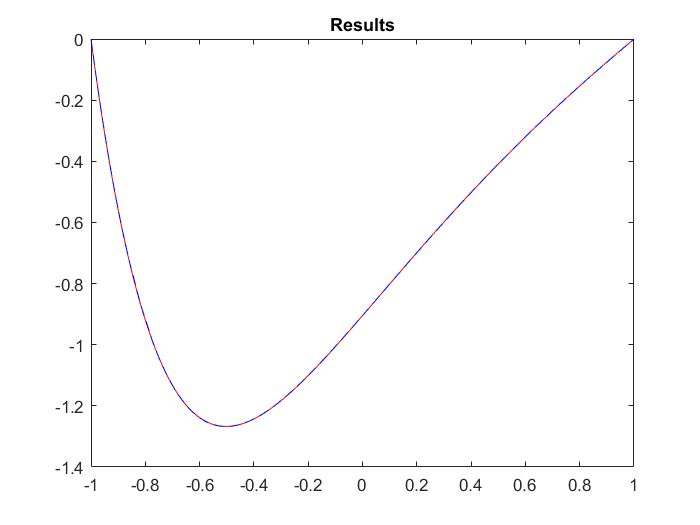

figure;
plot(X, y_matlab(1,:), '-r');
hold on;
fplot(y_galerkin, [a b], '--b');
%fplot(y_collocations, [a b], '-.g');
title('Results');
hold off;

#### Functions:

function dydx = odefun(x_, y)
    %p = @(x_actual)(subs(P(), x, x_actual));
    syms x;
    p = P();
    q = Q();
    r = R();
    f = F();
    dy_2 = subs((q/p) * y(2) + (r/p) * y(1) - (f/p), x, x_);
    dydx = [
        y(2);
        dy_2
    ];
end

function res = bcfun(ya, yb)
    res = [
        ya(1);
        yb(1)
    ];
end